# ENGR105    ---    Problem Set 1    ---    Introduction to MATLAB

## Due: Friday, 9/4/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW1.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu.

                    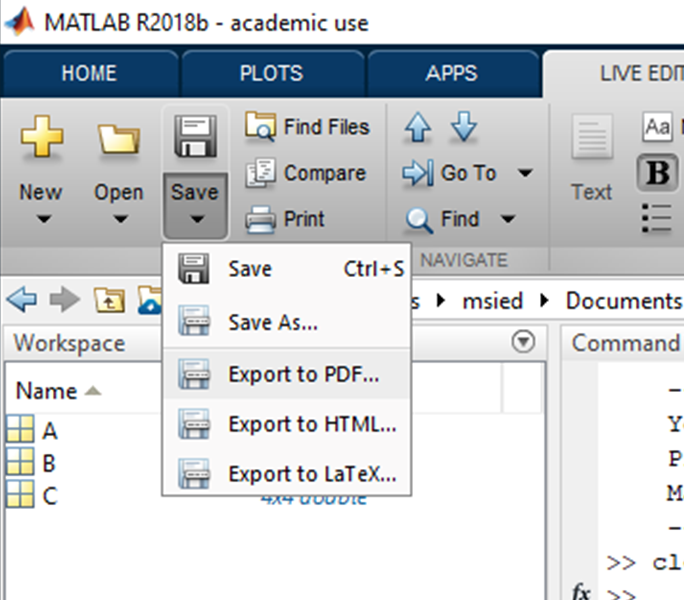

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

                   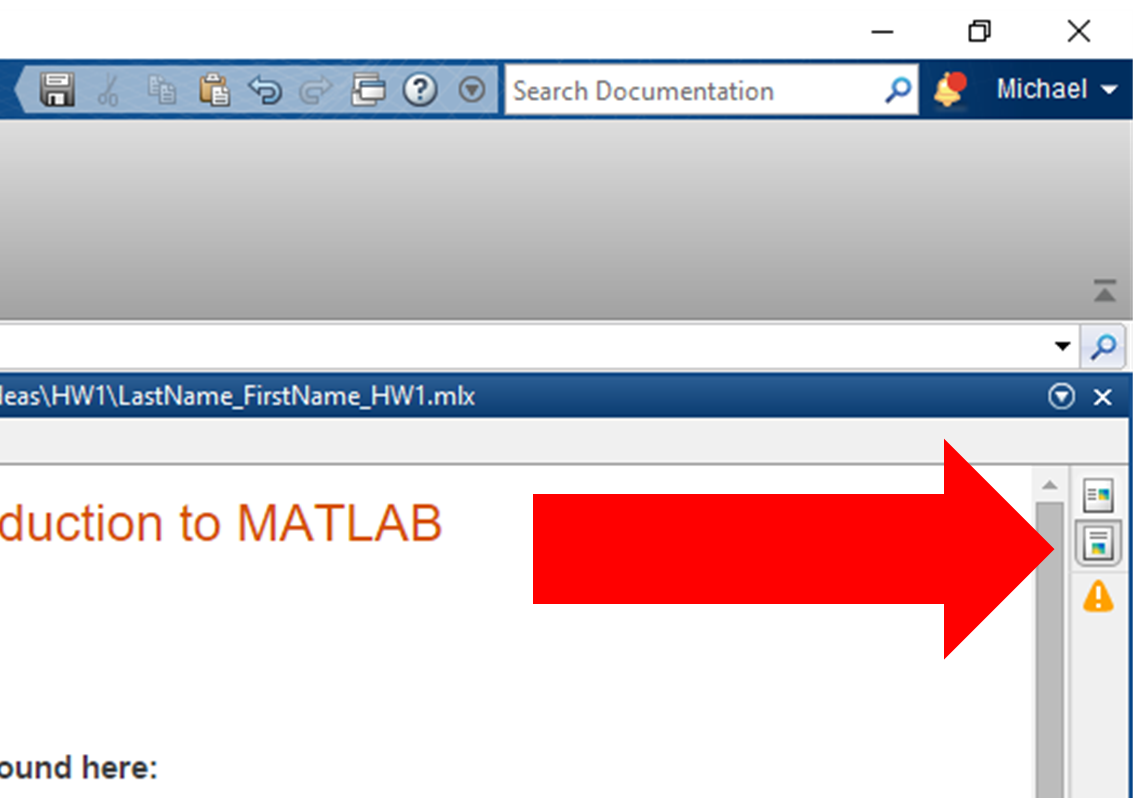

#### Purpose of this problem set:

- Develop familiarity with using MATLAB LiveScript documents. Understand how to run code in specific sections and over the entire document.

- Gain confidence reading and modifying code in MATLAB.

- Understand what is expected from HW assignments. Remember to strive for code that is **c**orrect, **c**omputationally efficient, and **c**lear.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (30 pts): Vectors

Throughout this course, you will create many vectors, matrices, and arrays in the process of solving programming, science, and engineering problems. A vector is a one dimensional (either one row or one column) array of numerical data that **you will use often**, for example to define values to plot, to discuss 2D or 3D particle or object motion, or when working with data from a sensor, to name just a few examples.

Vectors can be manually defined, e.g. using square brackets (`[]`) to concatanate multiple scalars into a vector:

However, for simiplicity, because explcitly defining vectors becomes complicated when we work with large vectors, we use the buit-in capabilities of MATLAB to create vectors. **Run the following code (**`Cntl + Enter`**) to create vectors A, B, and C**. There is no semicolon (`;`) at the end of the line, so you should see the output of each vector.

% Create an example vector, A, using slice (or colon) notation to increment from 1 to
% 5 in steps of 2. This is one of the most common ways to create a vector.
A = 1:2:5

A =      1     3     5


% Create an example vector, B, with 7 evenly spaced entities between (and including) 1
% and 5
B = linspace(1,5,7)

B =     1.0000    1.6667    2.3333    3.0000    3.6667    4.3333    5.0000


% Create an example vector, C, with 5 entries, where each entry is 1. The
% "zeros" command creates a similar vector of zeros.
C = ones(1,5)

C =      1     1     1     1     1


Using the above as examples (*do NOT* *manually define each entry in the vector*), produce one line of code to create the following vectors. **For this problem, please do ****not**** suppress the code output with semicolons (**`;`**) at the end of each line. **After running this section, the output from each line of code should match the desired vector.

**a)** a` = [2     4     6     8]`

A = 2:2:8

A =      2     4     6     8


**b)** b` = [9     8     7     6]`

B = 9:-1:6

B =      9     8     7     6


**c)** `c = [2.0000    2.2500    2.5000    2.7500    3.0000]`

C = linspace(2,3,5)

C =     2.0000    2.2500    2.5000    2.7500    3.0000


**d)** `d = [5     5     5]`

D = 5*ones(1,3)

D =      5     5     5


**e)** `e = [1.0000    0.8000    0.6000    0.4000    0.2000    0]`

E = linspace(1,0,6)

E =     1.0000    0.8000    0.6000    0.4000    0.2000         0


## PROBLEM 2 (20 pts):  Using the `help` function in MATLAB

Whether you are using MATLAB for the first time or are a seasoned user, you will use the `help` capabilities to refresh your memory or to learn about the required syntax for a given function. For example, the following line calls the `help` function for the `plot` command. 

help plot;

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

**Using the **`help`** call for the **`plot`** command (above), or by using the **`plot`** documentation,** modify the following code to create the desired output.

**a)** For the following plot of $y=x^2$, instead of plotting black points, **modify** the code so that the plot shows a **red, dashed line.**

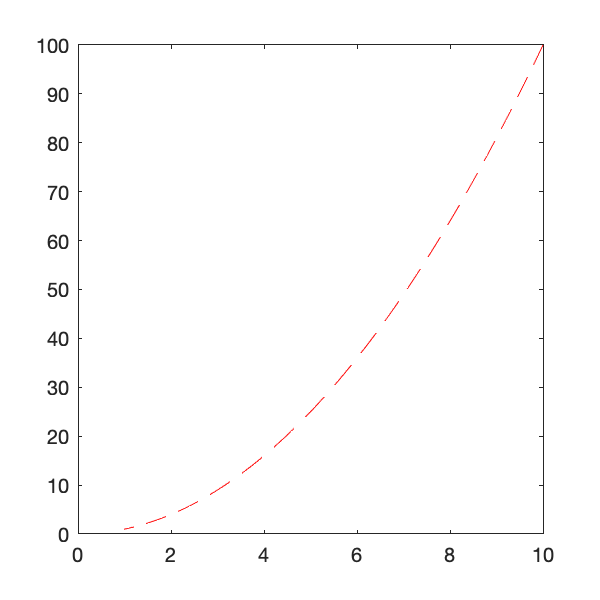

% Vector containing x values
x_values = 1:0.1:10;

% Plot y = x^2 for the x values specified above
figure('Position',[0,0,300,300]);
plot(x_values,x_values.^2,'r--')

**b)** For the following plot of $y=\sqrt{x}$, instead of plotting black points, **modify** the following code so that the plot shows a **blue, solid line with a line width of 2.**

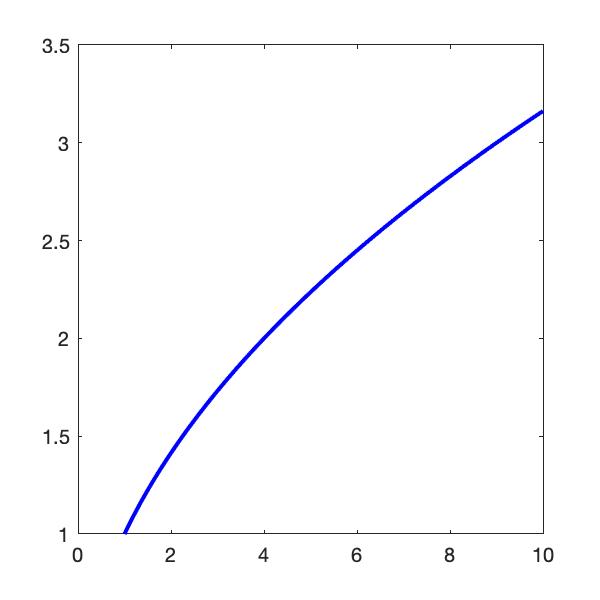

% Plot y = sqrt(x) for the x values specified above
figure('Position',[0,0,300,300]);
x = x_values;
y = sqrt(x_values);
plot(x,y,'b-', 'LineWidth', 2)

## PROBLEM 3 (10 pts): Commenting code

Commenting your code is extremely important, both to ensure that what you are doing is clear to others, but also to help you remember what you were doing when you revisit old code. The following code provides an example of a `for` loop, in which the contents (code inside the for loop) is repeated for index` k` equaling each value of the vector `1:10`. 

**Add comments to the following code **(using `%`, as above) so that it is clear what is happening here.

% iterates through a 10 times since the vector is from 1-10
%prints the numbers from 1-10
for k = 1:10
    
    disp(k);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



We will talk much more about loops in the next few weeks.

## PROBLEM 4 (25 pts): Calling functions 

Custom functions are typically saved as their own `.m` file in the directory that they will be called. For convenience and for the purpose of homework assignments in this course, functions can be saved at the end of the `.mlx` file, with a unique "code block" for each one. **Please check the end of this document to find two functions** to be used for answering the following questions.

**a)** Using the functions defined at the end of this `.mlx` file, calculate (and output) the average of [`2,3,6].`

% Calling the function to return the average of 2,3, and 6
hw1_p4_TWO(2,3,6)

ans = 3.6667

**b)** Using the functions defined at the end of this `.mlx` file, calculate (and output) the absolute value of the difference between 7 and 4.

% Calling the function to return the absolute value of the difference between 7 and 4
hw1_p4_ONE(7,4)

ans = 3

In both cases, **do not suppress the output with (**`;`**).**

## PROBLEM 5 (15 pts): m-files and Scripts

For most homework assignments, we will do everything in these `.mlx` files. However, in practice you will often create a script (as a `.m` file) to save, edit, and improve multiple (potentially many) lines of code to be performed. New .m files can be created directly from the MATLAB interface by selecting **NEW > Script**.

                            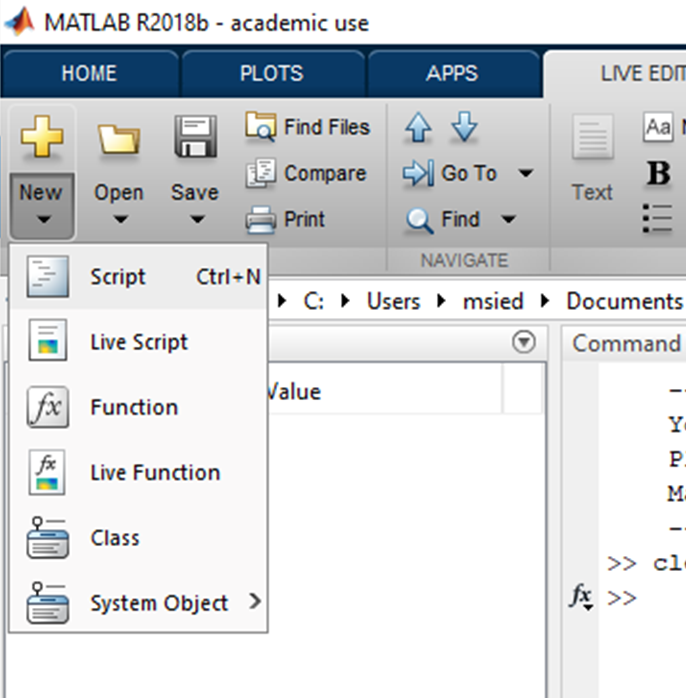

**a)** Create an m-file script named **HW1_P5.m** and paste the following code into it. Save this m-file in the same directory that contains this saved HW assignment. 

**b)** If you call a script (m-file) in the command line or in a LiveScript file, the code contained in the m-file will be executed. Call your script below. The output should be the matrix defined by the lines of code in **a)**.

% Call your script here
HW1_P5

     4     3     2     1
     8     6     4     2
    12     9     6     3
    16    12     8     4



You do not need to submit the m-file created in this problem but the output from** b)** should be visible.

# All functions are stored at the end of the .mlx file

% The following two functions are for PROBLEM 4 of this assignment
% Function hw1_p4a returns a scalar based on the input of three scalar
% values

function output = hw1_p4_TWO(a,b,c)
    output = (a+b+c)/3;
end

Note that when you have multiple functions at the end of a `.mlx` file, each one must be in its own block of code.

% Function hw1_p4b returns a scalar based on the input of two scalar
% values
function output = hw1_p4_ONE(a,b)
    output = abs(a-b);
end